# Controle preditivo com garantias de factibilidade recursiva e convergência para o ponto de equilíbrio desejado

**Dependências:**

Para executar este Live Script, é necessário ter instalado o Multiparametric Toolbox 3: [www.mpt3.org](http://www.mpt3.org)

São necessárias ainda as seguintes funções, apresentadas em aula:

`teste_redundancia.m`

`determina_oinf.m`

`dlqrcon.m`

**Exemplo: Servomecanismo rotacional**

clear, clc, close all

% Matrizes usadas no modelo da planta amostrada
A = [1 0.1;0 1]; B = [5e-3;0.1]; C = [1 0];

% Projeto DLQR
Q = diag([50,1]); R = 1;
[K,P] = dlqr(A,B,Q,R);

% Determinação dos valores de equilíbrio xbar, ubar 
% para uma dada referência rbar
rbar = pi; % Referência de pi radianos
aux = inv([A - eye(2) B;C 0])*[0;0;1];
Nx = aux(1:2); Nu = aux(3);
xbar = Nx*rbar;
ubar = Nu*rbar;

% Restrições: Sx*x <= bx, Su*u <= bu
Sx = [1 0;-1 0]; bx = [7*pi/6;pi/6];
Su = [1;-1]; bu = [5;2];

**Determinação de **$\mathcal{O}_\infty$

Af = A-B*K;
% Vetor de variáveis sujeitas a restrições: 
% psi(k) = Gamma x(k)
% Spsi psi(k) <= bpsi
Gamma = [eye(2);-K];
Spsi = blkdiag(Sx,Su);
bpsi = [bx;bu];

% Determinação do máximo conjunto admissível considerando o
% ponto de equilíbrio (xbar, ubar) desejado
% Vide slides 70 e 71 da Aula 6
max_iter = 10; 
[Sf,bf_til] = determina_oinf(Af,Gamma,Spsi,bpsi-[Sx*xbar;Su*ubar],max_iter);

Iteração 1 / 10

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.

Iteração 2 / 10

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.

Iteração 3 / 10

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.

Iteração 4 / 10

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.

Iteração 5 / 10

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.

Iteração 6 / 10

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.

Iteração 7 / 10

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.

Iteração 8 / 10

Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.



bf = bf_til + Sf*xbar;
% Oinf = {x : Sf*x <= bf}
Oinf = Polyhedron('H',[Sf bf]); % Declaração de Oinf como objeto do MPT Toolbox

**Determinação de **$\mathcal{D}$ : **Conjunto de condições iniciais para as quais o problema de programação quadrática é factível (abreviadamente: "Conjunto de condições iniciais factíveis")**

% Construção das matrizes An, Bn, Sxn, bxn, Sun, bun, Sn, bn
% Obs: n = negrito
% (Vide slide 15 da Aula 8)
% 
N = 12 % Digite o valor do horizonte N

N = 12

Sun = Su; An = A;
for i = 2:N
    Sun = blkdiag(Sun,Su);
    An = [An;A^i];
end
bun = repmat(bu,N,1);

n = size(B,1); p = size(B,2);
Bn = zeros(n*N,p*N);
Baux = mat2cell(zeros(n*N,p*N),n*ones(N,1),p*ones(1,N));
for i = 1:N
    for j = 1:i
        Baux{i,j} = (A^(i-j))*B;
    end
end
Bn = cell2mat(Baux);

Sxn = Sx;
for i = 2:N-1
    Sxn = blkdiag(Sxn,Sx);
end
Sxn = blkdiag(Sxn,Sf);
bxn = [repmat(bx,N-1,1);bf];

% Construção das matrizes Sw, bw
% (Vide slide 33 da Aula 8)

Sw = [Sxn*Bn Sxn*An;
      Sun zeros(size(Sun,1),n);
      zeros(size(Sx,1),p*N) Sx];
bw = [bxn; bun; bx];

% Operação de projeção empregando o MPT Toolbox
Pw = Polyhedron('H',[Sw bw]);
D = projection(Pw,p*N+1:p*N+n);

Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display"


% Apresentação gráfica de D e Oinf usando o plot do MPT Toolbox
plot(D,'Color','g'), hold on

Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display"

plot(Oinf)

Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.
Matlab Toolbox parameter "Display" found.


xlabel('x_1 (rad)'), ylabel('x_2 (rad/s)')

**Visualização de trajetórias obtidas com o controlador preditivo**

**Obs: **Notar que a função `quadprog` está sendo chamado com `options = optimset('display','off')` no final da rotina `dlqrcon. `Essa opção desabilita a apresentação de mensagens relacionadas ao resultado da otimização para cada instante de tempo k.

disp('Escolha a condição inicial com o mouse. Clique fora da região D para encerrar.')

Escolha a condição inicial com o mouse. Clique fora da região D para encerrar.


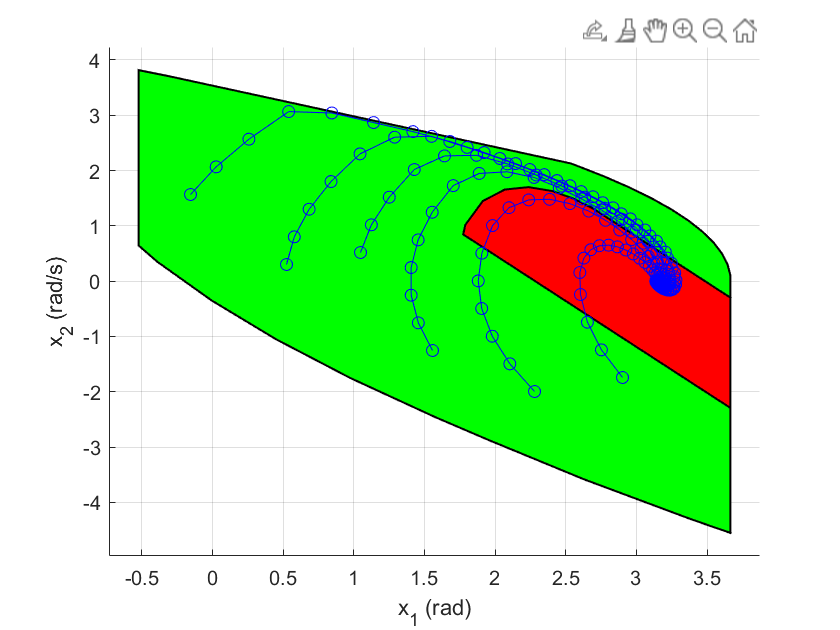

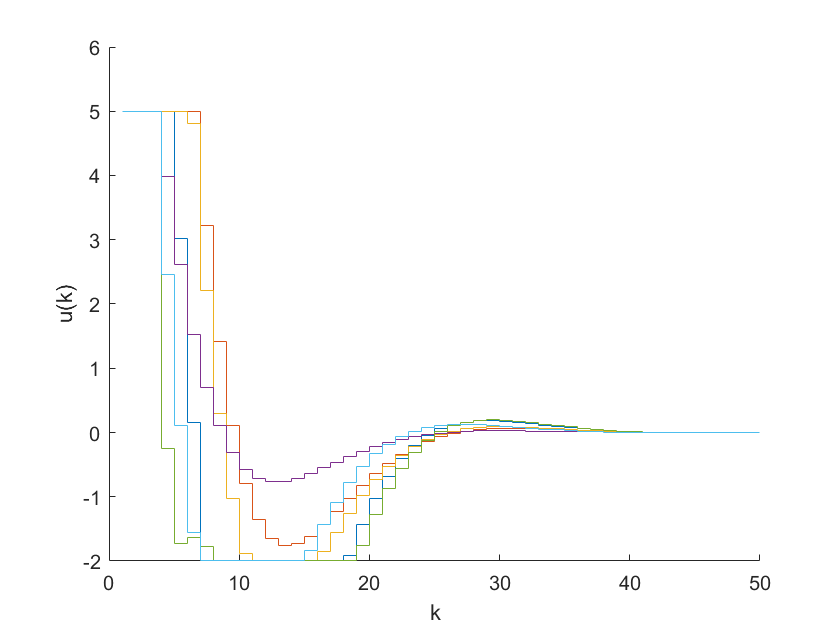

[x1,x2] = ginput(1); x0 = [x1;x2];

figure(2), xlabel('k'), ylabel('u(k)'), hold on
% Usando a representação de D no formato do MPT Toolbox:
while D.H(:,1:2)*x0 <= D.H(:,3) 
    x{1} = x0;
    for k = 1:50,
        un = dlqrcon(A,B,Q,R,P,N,Sx,bx,Su,bu,Sf,bf,x{k},xbar,ubar);
        u(k) = un(1);
        x{k+1} = A*x{k}+B*u(k);
    end
    X = [x{1,:}];
    figure(1), plot(X(1,:),X(2,:),'b-o');
    [x1,x2] = ginput(1); x0 = [x1;x2];
    figure(2), stairs(u) 
end